syms T V

R = 8.314;
Ttriple = 180.97;
Tcrit = 437.22;
Tfus = 180.15;

Proom = 10^5;
Pcrit = 5.34e+6;

antA = 4.29371;
antB = 995.445;
antC = -47.869;

Pant = @(T) (10^5)*10^(antA - (antB/(T + antC)));
b = 0.0778*R*Tcrit/Pcrit;
Ptriple = Pant(Ttriple);

H_vap = 33780;

omega = -1 - log10(Pant(0.7*Tcrit)/Pcrit);
k_small = 0.37464 + 1.5422*omega - 0.26992*omega^2;
alpha_T = @(T) (1 + k_small*(1 - sqrt(T./Tcrit)))^2;
a_T = @(T) (0.45724*(R^2)*(Tcrit^2)/Pcrit) * alpha_T(T);

Prb = @(T,V) R*T./(V - b) - a_T(T)/(V.*(V + b) + b*(V - b));

Vcrit = vpasolve(Prb(Tcrit,V) == Pcrit,V,[0 Inf]);
Trange_vap = linspace(Ttriple,Tcrit,100);

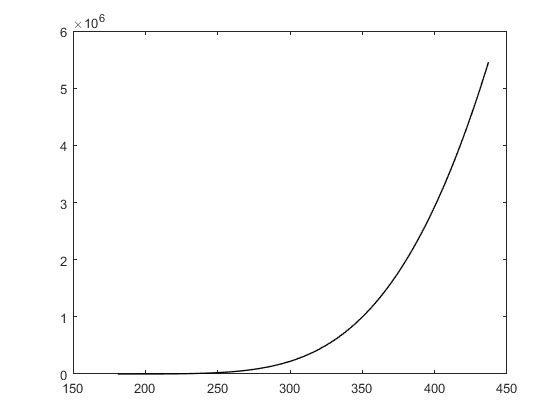

% VAP CURVE - if antoine equation
Pvap_ant = zeros(1,length(Trange_vap));

for i = 1:length(Trange_vap)
    Pvap_ant(i) = Pant(Trange_vap(i));
end

plot(Trange_vap,Pvap_ant,'k-','linewidth',1)
hold on

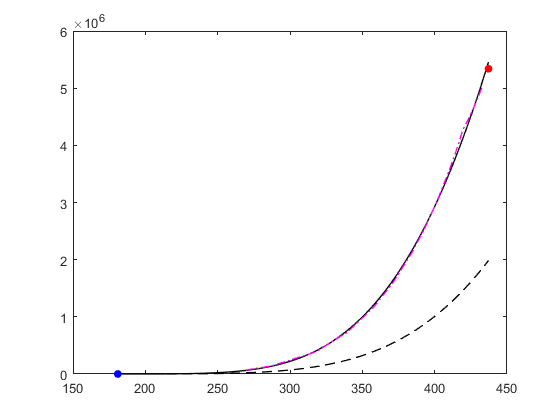

% VAP CURVE - if clausius clayperon eqn
Pclaus = @(T) Ptriple*exp(H_vap/R*(1/Ttriple - 1/T));
Pvap_claus = zeros(1,length(Trange_vap));

for i = 1:length(Trange_vap)
    Pvap_claus(i) = Pclaus(Trange_vap(i));
end

plot(Trange_vap,Pvap_claus,'k--','linewidth',1)

% VAP CURVE - PR EOS
plot(T_bin_nine,P_bin_nine,'m-.','linewidth',1)

% TRIPLE AND CRITICAL POINT 
plot(Ttriple,Ptriple,'b.','MarkerSize',20)
plot(Tcrit,Pcrit,'r.','MarkerSize',20)

% Setup of sublimation curve

syms A T
deltaHsub = 39.72086e+3;
B = deltaHsub/R;

Psub = @(A,T) 10^(A - B/T);
Trange_sub = linspace(0,Ttriple,100);

Aact = vpasolve(Psub(A,Ttriple) == Ptriple,A)

$$Aact = 28.214725646601988438016054326002$$

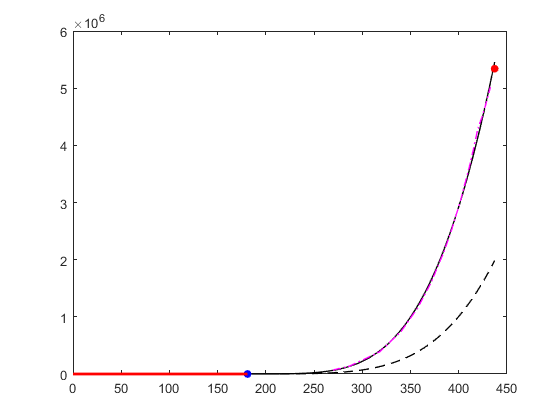


Psublim = zeros(1,length(Trange_sub));

for i = 1:length(Trange_sub)
    Psublim(i) = Psub(Aact,Trange_sub(i));
end

plot(Trange_sub,Psublim,'r-','linewidth',2)

% Setup of fusion curve

m = (Proom - Ptriple)/(Tfus - Ttriple)

m = -1.2187e+05

c = Ptriple - m*Ttriple

c = 2.2055e+07

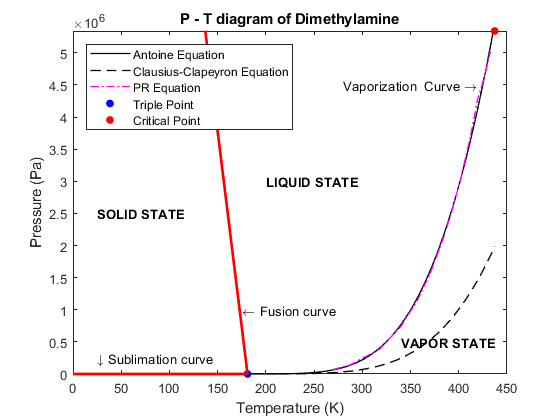


Trange_fus = linspace(0,Ttriple,100);

Pfus = @(T) m*T + c;
Pfusion = zeros(1,length(Trange_fus));

for i = 1:length(Trange_fus)
    Pfusion(i) = Pfus(Trange_fus(i));
end

plot(Trange_fus,Pfusion,'r-','linewidth',2)

txt1 = 'Vaporization  Curve \rightarrow';
text(420,4.5e+6,txt1,'HorizontalAlignment','right')

txt2 = '\leftarrow Fusion curve';
text(175,1e+6,txt2)

txt3 = '\downarrow Sublimation curve';
text(25,0.25e+6,txt3)

txt4 = 'SOLID STATE';
text(25,2.5e6,txt4,'fontweight','bold')
txt5 = 'LIQUID STATE';
text(200,3e6,txt5,'fontweight','bold')
txt6 = 'VAPOR STATE';
text(340,0.5e6,txt6,'fontweight','bold')
txt7 = 'STATE';
text()

title('P - T diagram of Dimethylamine')
xlabel('Temperature (K)')
ylabel('Pressure (Pa)')
ylim([0 Pcrit])
legend({'Antoine Equation','Clausius-Clapeyron Equation','PR Equation','Triple Point','Critical Point'},'Location','northwest')
hold off

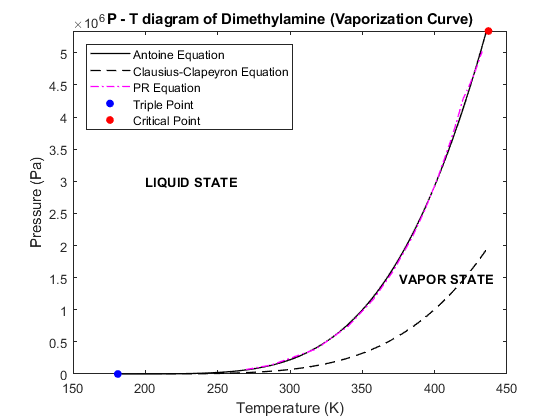

% PLOTTING VAP CURVE TO HAVE A BETTER VIEW
plot(Trange_vap,Pvap_ant,'k-','linewidth',1)
hold on
plot(Trange_vap,Pvap_claus,'k--','linewidth',1)
plot(T_bin_nine,P_bin_nine,'m-.','linewidth',1)
plot(Ttriple,Ptriple,'b.','MarkerSize',20)
plot(Tcrit,Pcrit,'r.','MarkerSize',20)

txt5 = 'LIQUID STATE';
text(200,3e6,txt5,'fontweight','bold')
txt6 = 'VAPOR STATE';
text(375,1.5e6,txt6,'fontweight','bold')

title('P - T diagram of Dimethylamine (Vaporization Curve)')
xlabel('Temperature (K)')
ylabel('Pressure (Pa)')
ylim([0 Pcrit])
legend({'Antoine Equation','Clausius-Clapeyron Equation','PR Equation','Triple Point','Critical Point'},'Location','northwest')
hold off

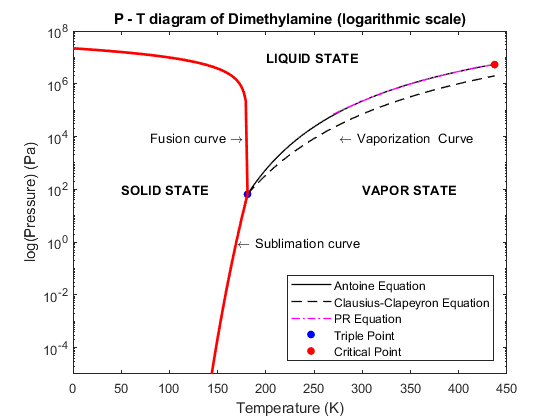

% PLOTTING LOG SCALE

plot(Trange_vap,Pvap_ant,'k-','linewidth',1)
hold on
plot(Trange_vap,Pvap_claus,'k--','linewidth',1)
plot(T_bin_nine,P_bin_nine,'m-.','linewidth',1)
plot(Ttriple,Ptriple,'b.','MarkerSize',20)
plot(Tcrit,Pcrit,'r.','MarkerSize',20)
plot(Trange_fus,Pfusion,'r-','linewidth',2)
plot(Trange_sub,Psublim,'r-','linewidth',2)

set(gca,'YScale','log')
txt1 = '\leftarrow Vaporization  Curve ';
text(420,1e4,txt1,'HorizontalAlignment','right')

txt2 = 'Fusion curve \rightarrow';
text(80,1e+4,txt2)

txt3 = '\leftarrow Sublimation curve';
text(170,1,txt3)

txt4 = 'SOLID STATE';
text(50,1e2,txt4,'fontweight','bold')
txt5 = 'LIQUID STATE';
text(200,1e7,txt5,'fontweight','bold')
txt6 = 'VAPOR STATE';
text(300,1e2,txt6,'fontweight','bold')

title('P - T diagram of Dimethylamine (logarithmic scale)')
xlabel('Temperature (K)')
ylabel('log(Pressure) (Pa)')
ylim([1e-5 1e8])
legend({'Antoine Equation','Clausius-Clapeyron Equation','PR Equation','Triple Point','Critical Point'},'Location','southeast')
hold off